Příklady k Procvičení:

clear all;
close all;

# Úvod do teorie pravděpodobnosti

## 1. Jevy

Příklad 1: Házíme hrací kostkou. Máte následující jevy: A= {2,4}, C= {2,5}

- Jaké jsou elementární jevy při hodu kostkou?                     

- Uveďte příklad složeného jevu.                                                  

- Jaký je doplněk k jevu A.                                                              

- Vytvořte jev B, který je disjunktní k jevu A.                                        

- Jaký je průnik jevu A a C.                                                               

- Jaké je sjednocení jevu A a C.                                                      

- Jaký je rozdíl jevů A a C. 

%a) [{1},{2},{3},{4},{5},{6}]
%b) [{1,2}]
%c) [{1,3,5,6}]
%d) B={1,5}
%e) [{2}]
%f) [{2,4,5}]
%g) [{4,5}]

## 2. Klasická pravděpodobnost

Příklad 3:Dřevěnou kostku o straně 5 cm natřeme na červeno a rozřežeme na krychle o hraně 1 cm. Určete pravděpodobnost, že vylosujete krychličku, která 

- Nebude obarvena.

- Bude obarvena na jedné stěně.

- Bude obarvena na dvou stěnách.

- Bude obarvena na třech stěnách.

n = 5^3;
%a)
k = 3^3;
Pa = k/n

Pa = 0.2160


%b)
k = 3^2 *6;
Pb = k/n

Pb = 0.4320


%c)
k = 3*12;
Pc = k/n

Pc = 0.2880


%d)
k = 8;
Pd = k/n

Pd = 0.0640

%kontrola => součet pravděpodobností musí být 1
P = Pa + Pb + Pc + Pd

P = 1

Příklad 4: Máme 10 druhů minerálek. 6 je perlivých, zbývající neperlivé. Určete pravděpodobnost, že z náhodně vybraných 3 minerálek budou

- Všechny perlivé. 

- Jedna perlivá, ostatní neperlivé.

- Jaké jsou elementární jevy pokusu?

- Dokažte výpočtem, že součet pravděpodobností přes všechny elementární jevy je roven 1.

n = 10;
%a)
Pa = nchoosek(6,3)*nchoosek(4,0)/nchoosek(10,3)

Pa = 0.1667

%b)
Pb = nchoosek(6,1)*nchoosek(4,2)/nchoosek(10,3)

Pb = 0.3000

%c) {perlivé,neperlivé}: [{0,3},{1,2},{2,1},{3,0}]
%d)
P4(1) = nchoosek(6,0)*nchoosek(4,3)/nchoosek(10,3)

P4 = 0.0333

P4(2) = nchoosek(6,1)*nchoosek(4,2)/nchoosek(10,3)

P4 =     0.0333    0.3000


P4(3) = nchoosek(6,2)*nchoosek(4,1)/nchoosek(10,3)

P4 =     0.0333    0.3000    0.5000


P4(4) = nchoosek(6,3)*nchoosek(4,0)/nchoosek(10,3)

P4 =     0.0333    0.3000    0.5000    0.1667


sum(P4)

ans = 1.0000

Příklad 5: Ve hře šťastných deset je v osudí 80 míčků, z nichž se losuje 20. Sázející vybere 10 čísel. Určete pravděpodobnost, že uhádne právě 0 až 10 čísel. 

warning off
P5(1) = nchoosek(10,0)*nchoosek(70,20)/nchoosek(80,20)

P5 = 0.0458

P5(2) = nchoosek(10,1)*nchoosek(70,19)/nchoosek(80,20)

P5 =     0.0458    0.1796


P5(3) = nchoosek(10,2)*nchoosek(70,18)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953


P5(4) = nchoosek(10,3)*nchoosek(70,17)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953    0.2674


P5(5) = nchoosek(10,4)*nchoosek(70,16)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953    0.2674    0.1473


P5(6) = nchoosek(10,5)*nchoosek(70,15)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953    0.2674    0.1473    0.0514


P5(7) = nchoosek(10,6)*nchoosek(70,14)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953    0.2674    0.1473    0.0514    0.0115


P5(8) = nchoosek(10,7)*nchoosek(70,13)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953    0.2674    0.1473    0.0514    0.0115    0.0016


P5(9) = nchoosek(10,8)*nchoosek(70,12)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953    0.2674    0.1473    0.0514    0.0115    0.0016    0.0001


P5(10) = nchoosek(10,9)*nchoosek(70,11)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953    0.2674    0.1473    0.0514    0.0115    0.0016    0.0001    0.0000


P5(11) = nchoosek(10,10)*nchoosek(70,10)/nchoosek(80,20)

P5 =     0.0458    0.1796    0.2953    0.2674    0.1473    0.0514    0.0115    0.0016    0.0001    0.0000    0.0000


sum(P5)

ans = 1.0000

Příklad 6: 20 studentů má být rozděleno na 4 stejně početné skupiny. Jaká je pravděpodobnost, že A a B budou ve stejné skupině?

%A může jít do jakékoli skupiny
%B musí jít pouze do skupiny ve které je A takže má pravděpodobnost trefy
%1/19
P = 4*1/19

P = 0.2105

Příklad 7: Jaká je pravděpodobnost, že z náhodně poskládaných písmen A,A,B,C,D,E,E sestrojíte slovo ABECEDA?

%Jedná se o Permutace s opakováním
delka = length('abeceda');
P = 1/(factorial(delka)/(factorial(2)*factorial(2)))

P = 7.9365e-04

Příklad 8: Jaká je pravděpodobnost, že mezi 3 mariášovými kartami náhodně vytažených z balíčku bude právě 1 eso?

P = nchoosek(4,1)*nchoosek(28,2)/nchoosek(32,3)

P = 0.3048

Příklad 10: Postupně vyndávám koule z urny, kde jsou 3 bílé, 5 černých a 4 červené koule. Jaká je pravděpodobnost, že červenou vytáhnu dříve než bílou? Koule nevracíme. 

n = 3 + 5 + 4;
P10(1)=4/n;
P10(2)=(5/n)*(4/(n-1))

P10 =     0.3333    0.1515


P10(3)=(5/n)*(4/(n-1))*(4/(n-2))

P10 =     0.3333    0.1515    0.0606


P10(4)=(5/n)*(4/(n-1))*(3/(n-2))*(4/(n-3))

P10 =     0.3333    0.1515    0.0606    0.0202


P10(5)=(5/n)*(4/(n-1))*(3/(n-2))*(2/(n-3))*(4/(n-4))

P10 =     0.3333    0.1515    0.0606    0.0202    0.0051


P10(6)=(5/n)*(4/(n-1))*(3/(n-2))*(2/(n-3))*(1/(n-4))*(4/(n-5))

P10 =     0.3333    0.1515    0.0606    0.0202    0.0051    0.0007


sum(P10)

ans = 0.5714

## 3. Geometrická pravděpodobnost

Příklad 11: Ve čtverci o délce hrany 3 cm je kružnice o poloměru 1 cm. Jaká je pravděpodobnost, že náhodně zvolený bod ze čtverce je zároveň uvnitř kružnice.

ctverec = 3^2;
kruh = pi*1^2

kruh = 3.1416

P=kruh/ctverec

P = 0.3491

Příklad 12: Dva lidé si dají schůzku mezi 12 a 13. hodinou. Přijdou v tomto čase zcela náhodně. Jaká je pravděpodobnost, že se setkají, přichází-li nezávisle a čeká-li jeden na druhého přesně 15 minut.

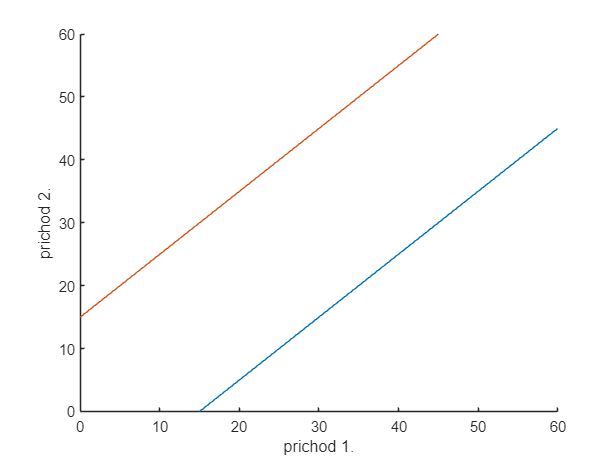

%vodorovná osa příchod prvního
%svislá osa příchod druhého
%diagonála přijsou ve stejný čas
x = linspace(15,60);
y = linspace(0, 45);
hold on
plot(x,y)
plot(y,x)
xlabel('prichod 1.');
ylabel('prichod 2.');
hold off

P = 1-(45*45)/(60*60)

P = 0.4375

## 4. Vlastnosti pravděpodobnosti, nezávislosti jevů, Bayesova věta

Příklad 17: Z balíčku 32 mariášových karet náhodně vytáhneme jednu kartu. Jev A spočívá ve vytažení žaludové karty, jev B ve vytažení esa. Určete, zda jevy jsou nezávislé a pokud ano určete pravděpodobnost nastolení obou jevů současně. 

%Oba jevy jsou nezávislé
%Můžeme vytáhnout pouze jednu kartu, tak, aby vyhovbovala oběma jevům
%jinak by se dalo vypočítat P = (8/32) * (4/32); 8 zaludových karet a 4 esa
P=1/32

P = 0.0312

Příklad 18: Máte zadání z příkladu 15, určete, zda jevy jsou vzájemně nezávislé. Zjistěte podmíněnou pravděpodobnost toho, že nastane jev A za podmínky, že nastal jev B.

Pa=0.3;
Pb=0.5;
Papb = 0.1;
%oba jevy jsou závyslé (mají mezi sebou průnik)
%Podmíněná pravděpodobnost ze vzorce
Pab = Papb/Pb

Pab = 0.2000

Příklad 19: V populaci je 20 % lidí se srdeční chorobou; 40 % populace jsou kuřáci. 12 % populace jsou kuřáci se srdeční chorobou. Jaká je pravděpodobnost, že:

- člověk má srdeční chorobu za předpokladu, že je kuřák,

- člověk má srdeční chorobu za předpokladu, že je nekuřák.

%a)
Pa = 0.12/0.4

Pa = 0.3000

%b)
Pb=0.08/0.6

Pb = 0.1333

Příklad 20: Na závodech na 110 m překážek zvítězí běžec A s pravděpodobností 0.3; běžec B s pravděpodobností 0.2. Při závodu běžec A spadl na překážce. Jaká je pravděpodobnost, že běžec B závod vyhraje.

Pa = 0.3;
Pb = 0.2;
PaDop = 0.7;
P=Pb/PaDop

P = 0.2857

Příklad 21: Výrobek je s pravděpodobností 0.8 zařazen do 1. jakostní skupiny, s pravděpodobností 0.1 do druhé, s pravděpodobností 0.1 bude do třetí. Pravděpodobnost, že výrobek bude v provozuschopném stavu po stanovenou dobu je pro jednotlivé jakostní skupiny 0.8; 0.6 a 0.3. Jaká je pravděpodobnost, že  náhodně získaný výrobek bude v provozuschopném stavu po stanovenou dobu. 

P = 0.8*0.8 + 0.1*0.6 + 0.1*0.3

P = 0.7300

Příklad 22: Automat A vyrobí za směnu třikrát víc výrobků než automat B. Přičemž automat A má zmetkovitost 0.01 a automat B 0.002. Výrobky se vhazují do stejné krabice. Jaká je pravděpodobnost, že náhodně vybraný výrobek není zmetek. 

A = 3000;
B = 1000;
PA = 0.01*A;
PB = 0.002*B;
P = 1 - (PA+PB)/(A+B)

P = 0.9920

Příklad 23: Pravděpodobnost, že selže aktivní hasicí systém při požáru je 5 %. Pravděpodobnost, že selže signalizace na centrálním pultu je 8 %. Pravděpodobnost, že selžou oba systémy najednou je 3 %. 

- Jaká je pravděpodobnost, že selže hasicí systém, ale nikoliv signalizace. 

- Zapůsobí oba dva systémy.

Ph = 0.05;
Pp = 0.08;
Po = 0.03; %h průnik p
%a)
Pa = Ph - Po

Pa = 0.0200

%b)
Pb = 1 - Ph - Pp + Po

Pb = 0.9000

Příklad 27: V první urně je 6 bílých a 3 černé koule. V druhé urně je 5 bílých a 1 černá koule. Náhodně zvolíme urnu a vytáhneme jednu kouli. Jaká je pravděpodobnost, že bude bílá.

Pu = 1/2;
Pu1 = 6/9;
Pu2 = 5/6;

P=Pu*(Pu1 + Pu2)

P = 0.7500

Příklad 28: Jeden ze 3 střelců s pravděpodobnostmi zásahu 0.3, 0.5 a 0.8 vystřelil a zasáhl. Jaká je pravděpodobnost, že střílel druhý střelec. 

Pa = 0.3;
Pb = 0.5;
Pc = 0.8;
P = (0.5*1/3)/(0.3*1/3 + 0.5*1/3 + 0.8*1/3)

P = 0.3125

Příklad 29: Výrobní linka produkuje pouze 60 % kvalitních výrobků. Proto se každý testuje. V případě, že je výrobek nekvalitní, bude s pravděpodobností 90 % odhalen a odstraněn. Naopak kontrola nepropustí 3 % kvalitních výrobků. 

- jaká je pravděpodobnost, že nekvalitní výrobek projde kontrolou,

- jaké je procento neporouchaných výrobků v odstraněných výrobcích. 

Ok = 0.6;
Ko = 0.4;
OKOK = Ok*0.97;
OKKO = Ok*0.03;
KOOK=Ko*0.1;
KOKO=Ko*0.9;
%a)
Pa = KOOK/(KOOK + OKOK)

Pa = 0.0643

%b)
Pb = OKKO/(KOKO+OKKO)

Pb = 0.0476

Příklad 30: Na vojenský cíl bylo čtyřikrát vystřeleno. Pravděpodobnost zásahu je 0.1. Jaká je pravděpodobnost, že cíl bude vyřazen, jestliže: 

- při 3 nebo 4 zásazích je pravděpodobnost zničení 0.9,

- při 2 zásazích 0.4,

- při 1 zásahu 0.1.

p4 = nchoosek(4,4)*0.1^4;
p3 = nchoosek(4,3)*0.1^3*0.9;
p2 = nchoosek(4,2)*0.1^2*0.9^2;
p1 = nchoosek(4,1)*0.1*0.9^3;
p0 = nchoosek(4,0)*0.9^4;
p = p0+p1+p2+p3+p4

p = 1.0000

vysl = p4*0.9+p3*0.9+p2*0.4+p1*0.1

vysl = 0.0519